# Otros tipos de gráficas bidimensionales

Aunque las gráficas *x-y* simples son el tipo más común de gráfica en ingeniería, existen muchas otras formas de representar datos.

## Gráficas polares

MATLAB proporciona capacidades de graficación con coordenadas polares mediante la función `polarplot`.

clear

x = 0:pi/100:pi;
y = sin(x);

polarplot(x,y)
title 'La función seno graficada en coordenadas polares es un círculo'

Para el tema de título, etiquetas, apariencia, etc.; se siguen las mismas consideraciones que para una gráfica *x-y* simple.

**Nota:** Estos tópicos fueron tratados en el subcapítulo 1 (**sc1**).

**Recomendación:** Para mayor información revisar la documentación.

## Gráficas logarítmicas

Una escala logarítmica (base 10) es conveniente cuando uma variable varía sobre muchos órdenes de magnitud, porque el amplio rango de valores se puede graficar sin comprimir los valores más pequeños.

Estas gráficas también son útiles para representar datos que varían exponencialmente.

En la siguiente tabla de muestran las funciones para realizar una gráfica *x-y* simple, y el resto son para generar gráficas logarítmicas.

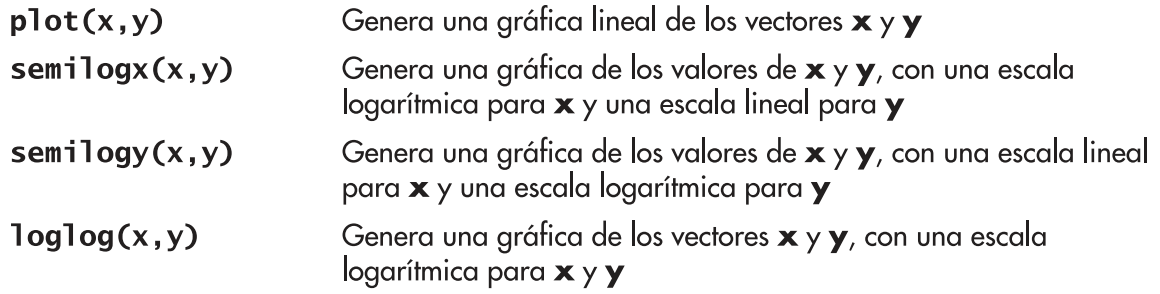

**Nota:** Recordar que el logaritmo de un número negativo o cero no existe, en los reales, por lo tanto, MATLAB emitirá un mensaje de advertencia y omitirá estos puntos, generando la gráfica con los puntos restantes.

clear

x = 0:.5:50;
y = 5*x.^2;

subplot(2,2,1);
    plot(x,y)
    title 'Polinomial - lineal/lineal'
    ylabel 'y'
    xlabel 'x'
    grid
    
subplot(2,2,2);
    semilogx(x,y)
    title 'Polinomial - log/lineal'
    ylabel 'y'
    xlabel 'x'
    grid

subplot(2,2,3);
    semilogy(x,y)
    title 'Polinomial - lineal/log'
    ylabel 'y'
    xlabel 'x'
    grid

subplot(2,2,4);
    loglog(x,y)
    title 'Polinomial - log/log'
    ylabel 'y'
    xlabel 'x'
    grid

**Recomendación:** Utilizar sangrías para facilitar la lectura del código.

## Gráficas de barras y de pastel

Las gráficas de barra, histograma y de pastel son formas populares de reportar datos. En la siguiente tabla se muestran algunas funciones usadas comúnmente para generarlas.

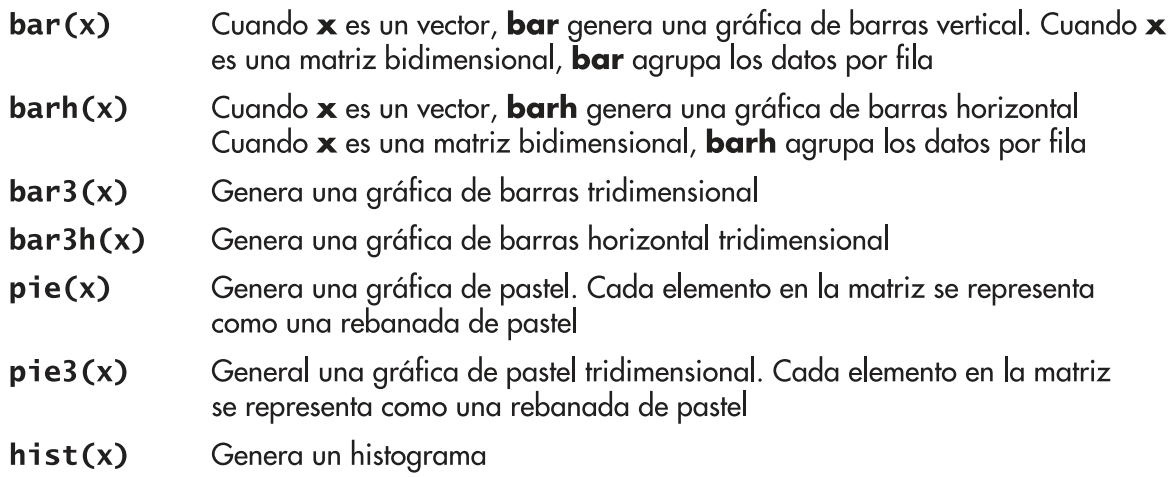

Se mostrará un ejemplo utilizando 4 funciones de la tabla.

clear

x = [1 2 5 4 8];
y = [
    x
    1:5
    ];

subplot(2,2,1)
    bar(x)
    title 'Una gráfica de barras del vector x'

subplot(2,2,2)
    bar(y)
    title 'Una gráfica de barras de la matriz y'

subplot(2,2,3)
    bar3(y)
    title 'Una gráfica de barras tridimensional de de la matriz y'

subplot(2,2,4)
    pie(x)
    title 'Una gráfica de pastel del vector x'

## Histogramas

Un histograma es un tipo especial de gráfica particularmente útil para el análisis estadístico de datos. Es una gráfica que muestra la distribución de un conjunto de valores.

Por defecto MATLAB crea 10 depósitos (categorías o *bins*) que están igualmente espaciadas entre los valores mínimo y máximo.

clear

x = [100 95 74 87 22 78 34 35 93 88 86 42 55 48];
hist(x)

Si se quiere cambiar el número de depósitos (*bins*) se ingresa un segundo argumento con el número de bins requeridos.

hist(x,25)

Por otra parte, si se requiere almacenar los datos del histograma basta con hacerlo en una variable.

A = hist(x)

**Nota:** Actualmente MATLAB sugiere trabajar con la función `histogram` para generar histogramas, pero esta función tiene algunas variaciones con respecto a la función `hist`. Se recomienda revisar la documentación para mayor información.

## Gráficas *x-y* con dos ejes *y*

En ocasiones resulta de gran utilidad sobreponer dos gráficas *x-y* en una misma figura, siempre y cuando se considere que las órdenes de magnitud de los valores *y* no sean muy diferentes. Si son muy diferentes no sería de utilidad generar este tipo de gráficas.

Analice el siguiente caso donde las órdenes de magnitud de la función `sin(x)` es muy diferente a la de la función `exp(x)`.

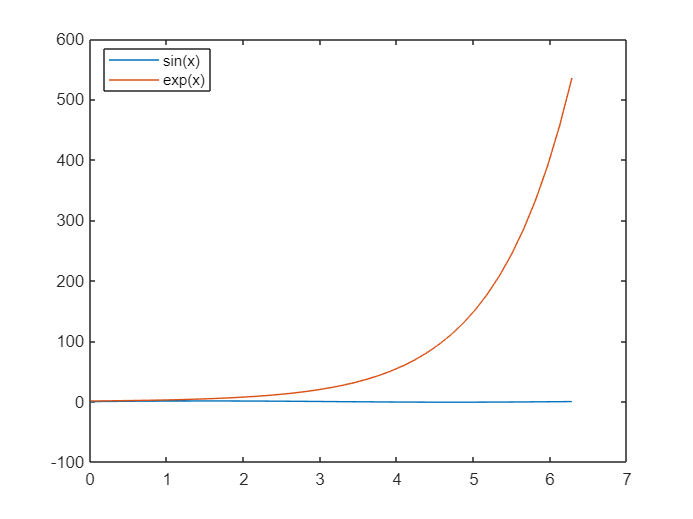

clear

x = 0:pi/20:2*pi;
y1 = sin(x);
y2 = exp(x);
plot(x,y1,x,y2)
legend('sin(x)', 'exp(x)','Location','best')

Parece que la función `sin(x)` es constante (lo que obviamente no es cierto). Esto se debe a la diferencia de las órdenes de magnitud de una función respecto a la otra.

La función `plotyy` permite crear gráficas con 2 ejes *y*.

Analizando el mismo ejemplo anterior, pero ahora usando esta función se tiene:

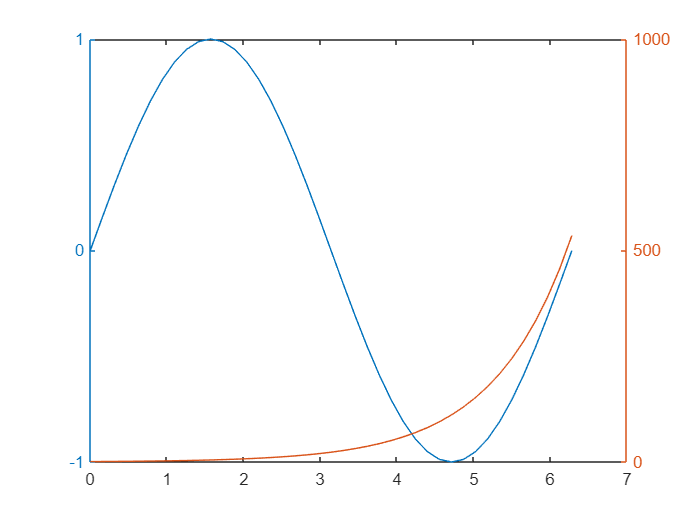

plotyy(x,y1,x,y2)

Para una mejor comparación se graficará las dos funciones en una misma figura.

subplot(1,2,1)
    plot(x,y1,x,y2)
    legend('sin(x)', 'exp(x)','Location','best')

subplot(1,2,2)
    plotyy(x,y1,x,y2)

Por otra parte, la función `plotyy` puede crear diferentes tipos de gráficas al agregarle un segundo argumento con el nombre de la gráfica.

subplot(1,2,1)
    plotyy(x,y1,x,y2,'semilogy')
    legend('sin(x)', 'exp(x)','Location','best')

subplot(1,2,2)
    plotyy(x,y1,x,y2,'semilogx')

En este caso se puede ingresar como argumento las funciones `loglog`, `semilogx`, `semilogy`, entre otras.

### Añadir la etiqueta a cada eje *y*

Para añadir la etiqueta a cada eje *y* basta con que guardemos nuestra gráfica en una variable y utilicemos índices para cada `label`.

f = plotyy(x,y1,x,y2)

f =   1×2 Axes array:

    Axes    Axes


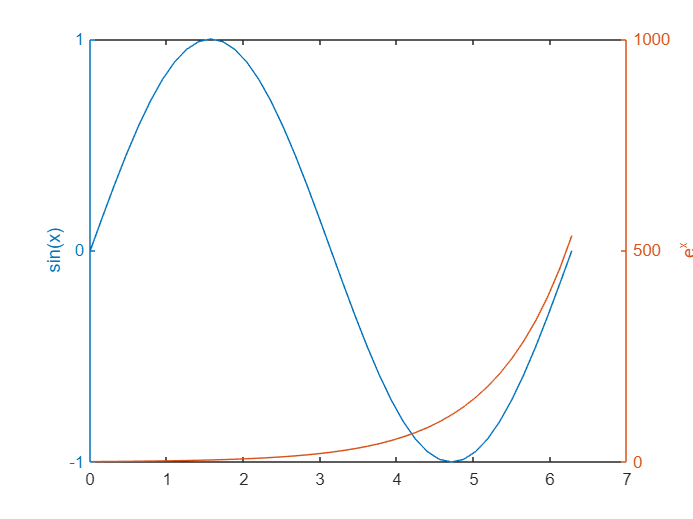

    ylabel(f(1),'sin(x)')
    ylabel(f(2),'e^x')